clc;clear all;close all;
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs=4/(s^2+7*s+9) %Planta continua

Gs =
 
        4
  -------------
  s^2 + 7 s + 9
 
Continuous-time transfer function.
Model Properties



Gs_sym = tfs_Syms(Gs)

$$Gs\_sym = \frac{4}{s^{2}+7\,s+9}$$

Sym_tfs(Gs_sym)

ans =
 
        4
  -------------
  s^2 + 7 s + 9
 
Continuous-time transfer function.
Model Properties



% syms s z
% G=4/(s^2+7*s+9)
% Ts=0.5
% Gz_EulerBackward=subs(G,s,(1-z^-1)/Ts)
% step(Sym_tfz(Gz_EulerBackward,Ts))
% % Gz_EulerForward=subs(G,s,(z-1)/Ts)
% Gz_Tustin=subs(G,s,2*(z-1)/(z+1)/Ts)
% Sym_tfz(Gz_Tustin,Ts)





%Ejercicios tustin, backward, forward
clear all; close all, clc;
syms z s
Ts = 0.1

Ts = 0.1000

Gs = 1/((s+1)*(s^2+s+1))

$$Gs = \frac{1}{\left(s+1\right)\,\left(s^{2}+s+1\right)}$$

Gz_EulerBackward = subs(Gs,s,(1-z^-1)/Ts) %EulerBackward

$$Gz\_EulerBackward = -\frac{1}{\left(\frac{10}{z}-11\right)\,\left({\left(\frac{10}{z}-10\right)}^{2}-\frac{10}{z}+11\right)}$$

Gz_EulerForward = subs(Gs,s,(z-1)/Ts) %Gz_EulerForward

$$Gz\_EulerForward = \frac{1}{\left(10\,z-9\right)\,\left(10\,z+{\left(10\,z-10\right)}^{2}-9\right)}$$

Gz_Tustin=subs(Gs,s,2*(z-1)/(z+1)/Ts)

$$Gz\_Tustin = \frac{1}{\left(\frac{10\,\left(2\,z-2\right)}{z+1}+1\right)\,\left(\frac{100\,{\left(2\,z-2\right)}^{2}}{{\left(z+1\right)}^{2}}+\frac{10\,\left(2\,z-2\right)}{z+1}+1\right)}$$

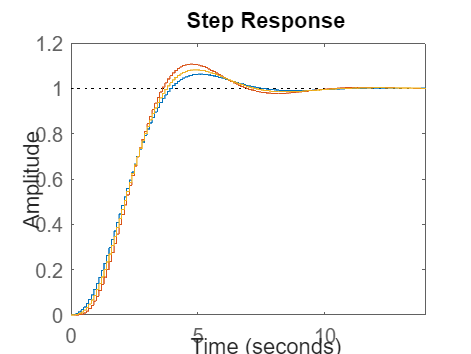


step(Sym_tfz(Gz_EulerBackward,Ts),10); hold on;
step(Sym_tfz(Gz_EulerForward,Ts),10)
step(Sym_tfz(Gz_Tustin,Ts),10)

step(Sym_tfs(Gs),10)
legend('Backward','Forward','Tustin','S')


function Zz = Sym_tfz(Gz,ts)
   [num_z, den_z] = numden(Gz); 
    num_coeff = sym2poly(num_z);
    den_coeff = sym2poly(den_z); 
    z = tf('z', ts); 
    Zz = zpk(tf(num_coeff, den_coeff, ts)); 
end

function Ss = Sym_tfs(Gs)
   [num_s, den_s] = numden(Gs); 
    num_coeff = sym2poly(num_s);
    den_coeff = sym2poly(den_s); 
    s = tf('s'); 
    Ss = tf(num_coeff, den_coeff); 
end

function Ss = tfs_Sym(Gs) 
    syms s
    [num, den] = tfdata(Gs, 'v'); 
    Ss = poly2sym(num, s) / poly2sym(den, s); 
end

function Zz = tfz_Sym(Gz) 
    syms z
    [num, den] = tfdata(Gz, 'v'); 
    Zz = poly2sym(num, z) / poly2sym(den, z); 
end